lid = LIDAR('COM11')

lid =   LIDAR with properties:

        lidar: [1×1 serial]
     pol_data: []
    cart_data: []


data = lid.scan(1000000);

  Columns 1 through 11

         510         510         510         539         544         544         539         532         529         529         529

  Columns 12 through 22

         529         529         512         512         512         514         516         519         524         526         526

  Columns 23 through 33

         528         526         528         524         532         532         552         561         565         598         602

  Columns 34 through 44

         602         602         567         562         560         557         560         560         566         593         600

  Columns 45 through 55

         604         604         600         581         553         545         545         543         543         528         528

  Columns 56 through 66

         528         528         535         537         537         539         548         552         553         553         552

  Columns 67 through 77

         552         5

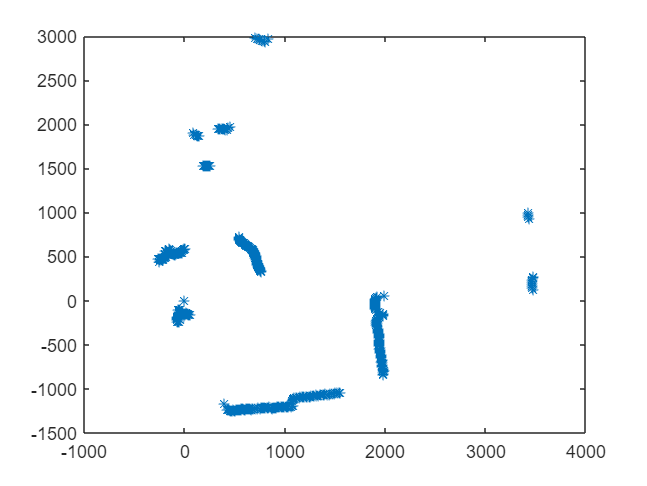

plot(data(1,:), data(2,:),'*')

left = data(2,:) > 0 & -2000 < data(1,:) < 2000

left = 1×682 logical array
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1


left = data(:,left)

left = 	1.0e+03 *

   -0.2550   -0.2523   -0.2496   -0.2609   -0.2603   -0.2574   -0.2521   -0.2460   -0.2417   -0.2388   -0.2359   -0.2330   -0.2300   -0.2198   -0.2170   -0.2141   -0.2121   -0.2100   -0.2083   -0.2074   -0.2052   -0.2022   -0.2000   -0.1962   -0.1940   -0.1895   -0.1894   -0.1863   -0.1901   -0.1900   -0.1881   -0.1956   -0.1934   -0.1899   -0.1864   -0.1722   -0.1674   -0.1635   -0.1594   -0.1569   -0.1536   -0.1519   -0.1557   -0.1540   -0.1514   -0.1478   -0.1432   -0.1352   -0.1254   -0.1203
    0.4417    0.4432    0.4448    0.4717    0.4777    0.4792    0.4764    0.4717    0.4706    0.4720    0.4735    0.4749    0.4764    0.4624    0.4638    0.4651    0.4682    0.4713    0.4754    0.4812    0.4843    0.4856    0.4887    0.4880    0.4911    0.4885    0.4972    0.4983    0.5182    0.5279    0.5328    0.5651    0.5701    0.5713    0.5724    0.5402    0.5365    0.5356    0.5337    0.5376    0.5385    0.5452    0.5722    0.5799    0.5847    0.5856    0.5826    0.5650


right = data(2,:) < 0 & -2000 < data(1,:) < 2000

right = 1×682 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0


right = data(:,right)

right = 	1.0e+03 *

    1.9050    1.9049    1.9047    1.9024    1.9001    1.8997    1.8992    1.9057    1.9151    1.9304    1.9525    1.9856    1.9847    1.9836    1.9397    1.9277    1.9185    1.9172    1.9159    1.9184    1.9169    1.9174    1.9167    1.9229    1.9251    1.9321    1.9351    1.9340    1.9319    1.9308    1.9383    1.9370    1.9395    1.9389    1.9374    1.9396    1.9408    1.9409    1.9380    1.9448    1.9418    1.9464    1.9490    1.9467    1.9520    1.9495    1.9518    1.9558    1.9569    1.9617
   -0.0117   -0.0234   -0.0351   -0.0467   -0.0584   -0.0700   -0.0817   -0.0937   -0.1060   -0.1187   -0.1321   -0.1466   -0.1588   -0.1710   -0.1792   -0.1900   -0.2010   -0.2128   -0.2246   -0.2368   -0.2486   -0.2607   -0.2726   -0.2855   -0.2979   -0.3112   -0.3239   -0.3359   -0.3478   -0.3598   -0.3736   -0.3857   -0.3986   -0.4109   -0.4230   -0.4360   -0.4488   -0.4614   -0.4733   -0.4876   -0.4996   -0.5135   -0.5270   -0.5393   -0.5537   -0.5659   -0.5796   -0.593

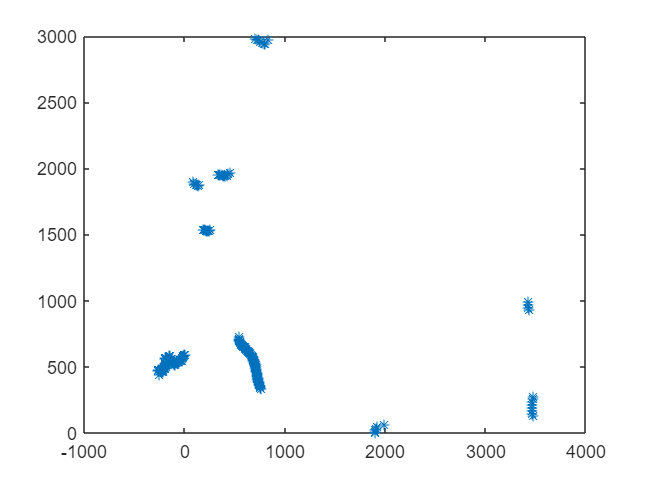

plot(left(1,:), left(2,:), '*')

fprintf(lid.lidar, 'QT');
fclose(lid.lidar);
clear lidar;
warning('on');
disp("the lidar has successfully been terminated")

the lidar has successfully been terminated


clear
clc
%camList = webcamlist()
cam = Camera();

cam.show()


[id,loc,pose] = cam.poses()

cam.disp_tags();

imshow(ans)

while true
    
    imshow(cam.disp_tags())
    pause(1)
end

[id, loc, poses] = cam.poses()

neo = NEO_M8U_USB("COM13") 

basic_data = neo.getBasic() 

  [robotArduino]= SETUPARDUINO('COM6')   

robotArduino =   arduino with properties:

                  Port: 'COM6'
                 Board: 'Nano33BLE'
         AvailablePins: {'D0-D13', 'A0-A7'}
  AvailableDigitalPins: {'D0-D13', 'A0-A7'}
      AvailablePWMPins: {'D0-D13'}
   AvailableAnalogPins: {'A0-A3', 'A6-A7'}
    AvailableI2CBusIDs: [0, 1]
AvailableSerialPortIDs: [1]
             Libraries: {'I2C', 'Servo'}
Show all properties


        % semi-colon left off to confirm Nano is connected

clear drive;
drive = servo(robotArduino, 'D3', 'MinPulseDuration', 1466*10^-6, 'MaxPulseDuration', 1536*10^-6);
writePosition(drive, 0.6085);      % always start servo-command at 0.5

function [robotArduino]= SETUPARDUINO(COMPORT)
% SETUPARDUINO creates and configures an arduino to be a simple robot test 
% controller. It requires which COM port your Arduino is attached to 
% as its input and returns an Arduino object called robotArduino
% D. Barrett 2022 Rev2
% Create a arduino object so that it can be used in functions
% a = arduino('setToYourComNumber','Uno','Libraries','Servo');
   robotArduino = arduino(COMPORT,'Nano33BLE',"Libraries",{'Servo','I2C'});
end